Dados:

clc; clear; close all;

% Aluno:
% ANDERSON NOGUEIRA SILVA

A = [0 1; -2 -3];
B = [0; 1];
C = [3 1];
D = 0;
T = 0.1;

Item a)

sys_c = ss(A, B, C, D);
sys_d = c2d(sys_c, T, 'zoh');

G_T = sys_d.A;
H_T = sys_d.B;
C_T = C;
D_T = D;

% Matrizes Discretizadas
G_T

G_T =     0.9909    0.0861
   -0.1722    0.7326


H_T

H_T =     0.0045
    0.0861


C_T

C_T =      3     1


D_T

D_T = 0

Item b)

Mc = ctrb(A, B);
posto_c = rank(Mc);


Mo = obsv(A, C);
posto_o = rank(Mo);

polos = eig(A);

posto_c % 2

posto_c = 2

posto_o % 2

posto_o = 2


det_Mc = det(Mc);
det_Mo = det(Mo);

det_Mc % != 0; controlável

det_Mc = -1

det_Mo % != 0; observável

det_Mo = 2


% Sistema controlável e observável

Item c)

[num, den] = ss2tf(G_T, H_T, C_T, D_T);

G_z = tf(num, den, T);

G_z


G_z =
 
   0.09969 z - 0.07382
  ----------------------
  z^2 - 1.724 z + 0.7408
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


Item d)

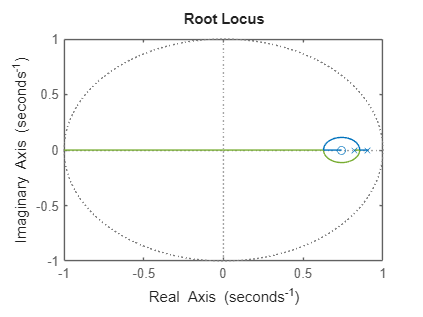

figure(1);
rlocus(G_z);

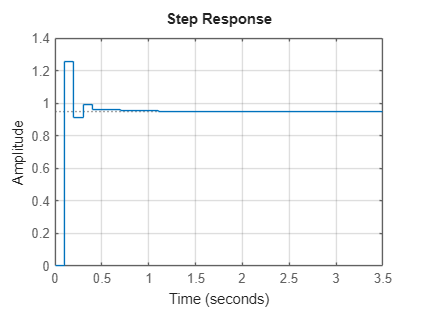


K_cr = 17.6; % Obtido com rlocus (ganho no polo z = -1)

K = K_cr - 5;

sys_fechado = feedback(K * G_z, 1);

figure(2);
step(sys_fechado);
grid on;